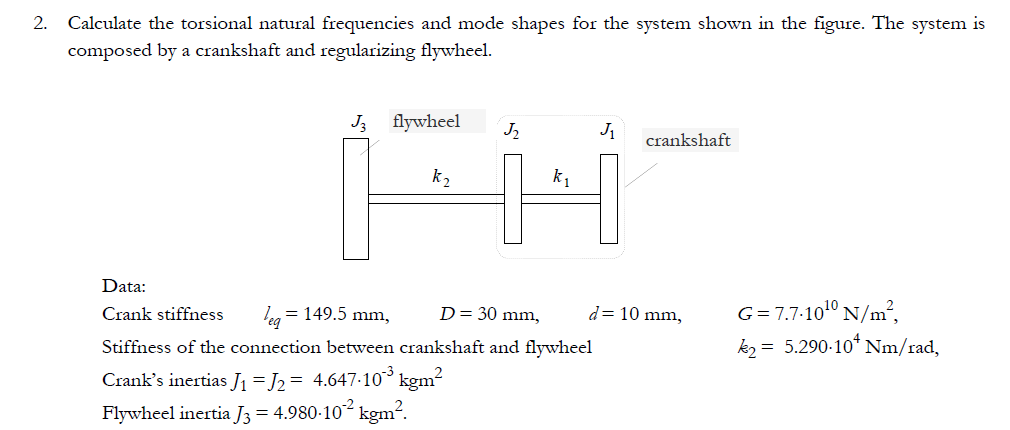

clear 
clc

leq=149.5e-3;
D=30e-3;
d=10e-3;
G=7.7e10;
k2=5.29e4;
J1=4.647e-3;
J2=J1;
J3=4.98e-2;

Ip=pi*(D^4-d^4)/32

Ip = 7.8540e-08

k1=G*Ip/leq

k1 = 4.0452e+04


K=[k2 -k2    0
   -k2 k2+k1 -k1
   0   -k1   k1];
M=[J3 0 0
   0 J2 0
   0 0 J1];

[phi,lambda]=eig(K,M);

% The first natural frequency is zero due to rigid body motion (rotation)
wt1=sqrt(lambda(2,2));
wt2=sqrt(lambda(3,3));

disp(' First torsional natural frequency [rad/s]:')

 First torsional natural frequency [rad/s]:


disp(wt1)

   2.1607e+03



disp(' ')

disp(' Second torsional natural frequency [rad/s]:')

 Second torsional natural frequency [rad/s]:


disp(wt2)

   5.0187e+03

